clear
% ECSE 563 assigmenet 4
% Ali Seifeldin
% https://github.com/Bakalala/MGCILL-ECSE-563

% Question 1

clear; clc; close all;

% Load table 1 data.
run("A4Q3_scopf_data.m")

%% Load levels and tolerance
loads = [300 400 600 700];    % MW
toler = 0.5;                  

nGen   = numel(co);
nCases = numel(loads);

G          = zeros(nGen, nCases);   % generator outputs (MW)
C_total    = zeros(1, nCases);      % total cost ($/h)
Lambda     = zeros(1, nCases);      % system lambda ($/MWh)
Profit     = zeros(nGen, nCases);   % per-unit profit ($/h)
TotalProfit = zeros(1, nCases);     % total profit ($/h)




%% Run ED for each load level and store results
for k = 1:nCases
    d = loads(k);

    [gk, Ck, lambdak] = ed(co, a, b, gmin, gmax, d, toler);

    G(:, k)       = gk;
    C_total(k)    = Ck;
    Lambda(k)     = lambdak;

    Cost_i       = co + a .* gk + 0.5 * b .* (gk.^2);  % each unit's cost
    Revenue_i    = lambdak * gk;                       % λ * g_i
    Profit_i     = Revenue_i - Cost_i;                 % profit_i

    Profit(:,k)   = Profit_i;
    TotalProfit(k) = sum(Profit_i);
end

%% Build a single results table (with profits)
Results = table( ...
    loads(:), ...        % Load
    Lambda(:), ...       % Lambda
    G(1,:).', ...        % g1
    G(2,:).', ...        % g2
    G(3,:).', ...        % g3
    Profit(1,:).', ...   % Profit1
    Profit(2,:).', ...   % Profit2
    Profit(3,:).', ...   % Profit3
    TotalProfit(:), ...  % Total system profit
    C_total(:), ...      % Total cost
    'VariableNames', { ...
        'Load_MW','Lambda', ...
        'g1_MW','g2_MW','g3_MW', ...
        'Profit1','Profit2','Profit3', ...
        'TotalProfit','TotalCost'} ...
);

%% Display the table
fprintf('=== ED algorithm Table ===\n');

=== ED algorithm Table ===


disp(Results)

    Load_MW    Lambda    g1_MW     g2_MW     g3_MW     Profit1    Profit2    Profit3    TotalProfit    TotalCost
    _______    ______    ______    ______    ______    _______    _______    _______    ___________    _________

      300      26.061    202.05     87.47        10    -187.65    -266.11    -701.39      -1155.1         8961  
      400      27.909       250    140.27        10     239.87    -55.674    -682.91      -498.71        11670  
      600      57.991       250       300    49.784     7760.3     8522.4    -350.43        15932        18850  
      700      61.994       250       300    149.84     8760.9     9723.1     49.061        18



%% Plot incremental cost curves and operating points for one load
% Choose which load to illustrate graphically:
d_plot  = 600;                            % MW (change if you like)
k_plot  = find(loads == d_plot, 1)

k_plot = 3

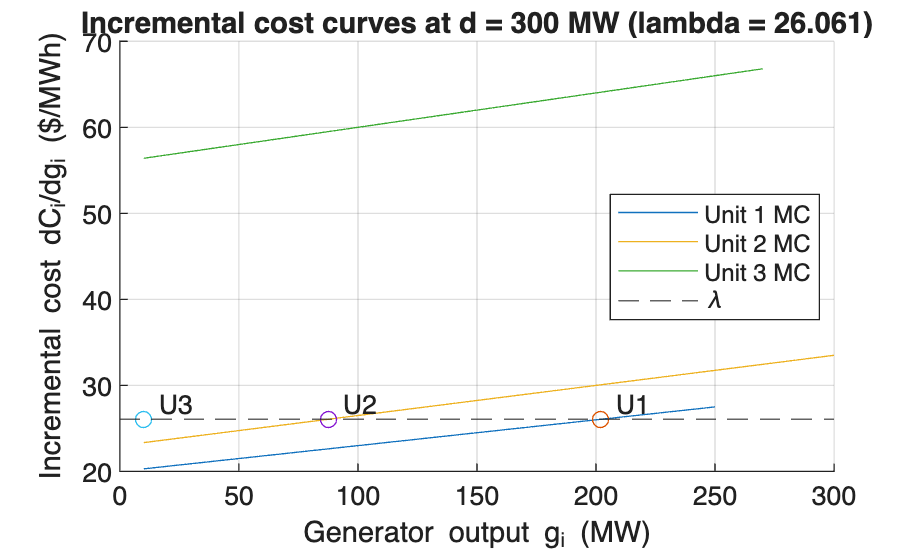

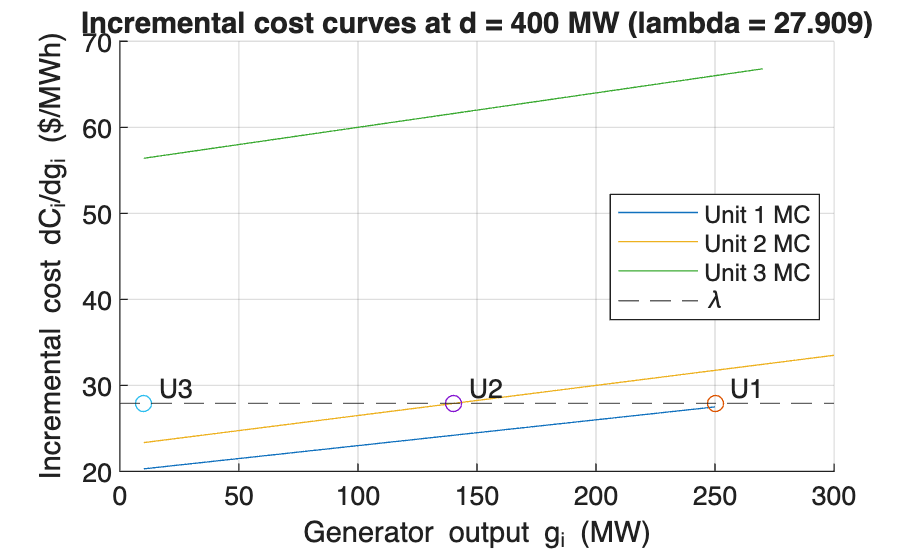

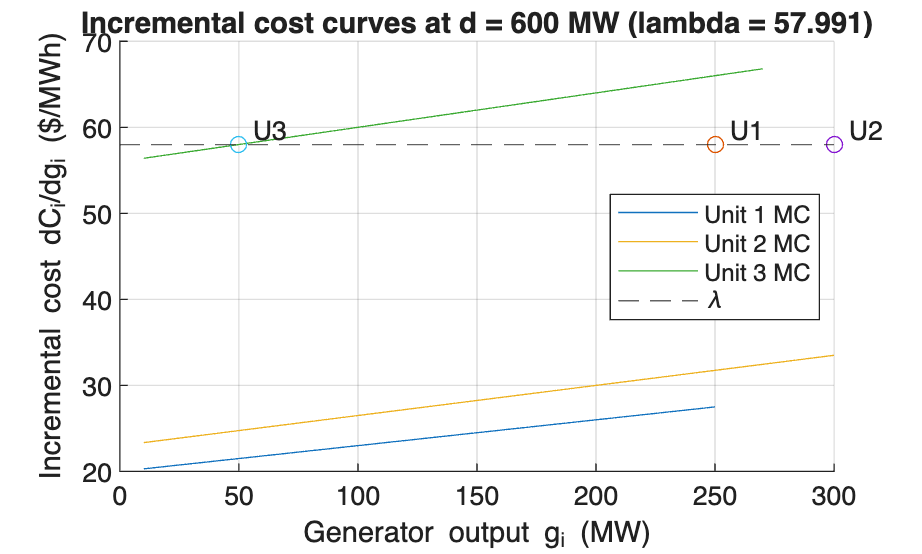

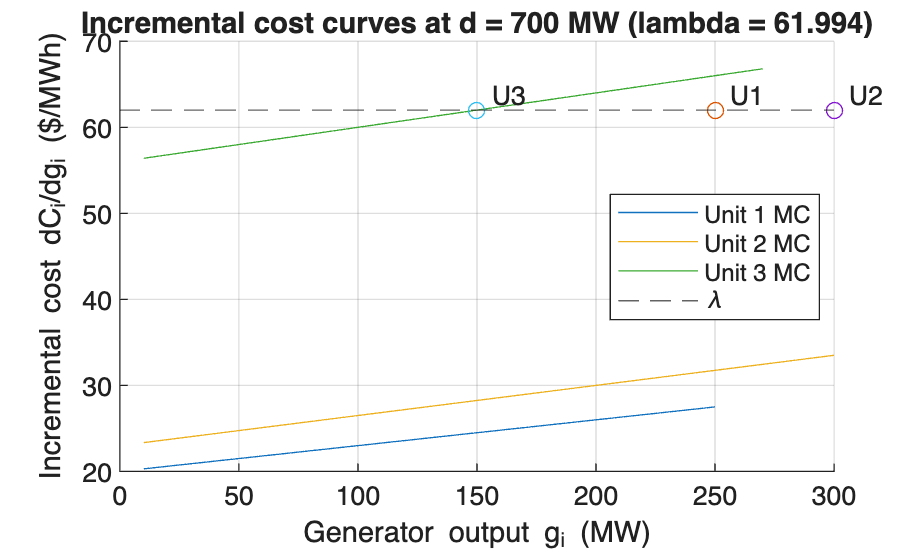


for k = 1:nCases

    d_plot  = loads(k);                            % MW (change if you like)

    if ~isempty(k)
        lambda_plot = Lambda(k);
        g_plot      = G(:, k);
    
        figure; hold on; grid on;
        title(sprintf('Incremental cost curves at d = %d MW (lambda = %.3f)', ...
            d_plot, lambda_plot));
        xlabel('Generator output g_i (MW)');
        ylabel('Incremental cost dC_i/dg_i ($/MWh)');
    
        for i = 1:nGen
            g_range = linspace(gmin(i), gmax(i), 200);
            mc      = a(i) + b(i) .* g_range;   % dC_i/dg_i = a_i + b_i*g_i
    
            plot(g_range, mc, 'DisplayName', sprintf('Unit %d MC', i));
            plot(g_plot(i), lambda_plot, 'o', 'HandleVisibility', 'off');
            text(g_plot(i), lambda_plot, sprintf('  U%d', i), ...
                'VerticalAlignment', 'bottom');
        end
    
        yline(lambda_plot, '--', 'DisplayName', '\lambda');
        legend('Location', 'best');
    end
end


%% Compute minimum outputs to recover fixed costs at each lambda
% Solve for each unit and each lambda:
%   lambda * g = c0 + a*g + 0.5*b*g^2
% -> 0.5*b*g^2 + (a - lambda)*g + c0 = 0

g_break_even = NaN(nGen, nCases);

for k = 1:nCases
    lam = Lambda(k);

    for i = 1:nGen

        % Solve A*g^2 + B*g + C = 0 using MATLAB's roots()
        coeffs = [0.5*b(i),  a(i) - lam,  co(i)];
        r = roots(coeffs);

        % Select real, positive roots only
        r = r(imag(r)==0 & r > 0);

        if ~isempty(r)
            g_break_even(i, k) = min(r);   % smallest positive real root
        end
    end
end


%% Table: Minimum outputs to recover fixed costs at each lambda
% (solution of lambda*g = c0 + a*g + 0.5*b*g^2)

BreakEven = table( ...
    loads(:), ...             % Load for each case
    Lambda(:), ...            % Lambda for each case
    g_break_even(1,:).', ...  % g_be1 for each case (column)
    g_break_even(2,:).', ...  % g_be2 for each case
    g_break_even(3,:).', ...  % g_be3 for each case
    'VariableNames', {'Load_MW','Lambda','g_be1_MW','g_be2_MW','g_be3_MW'} ...
);

%'Minimum outputs to recover fixed costs at each lambda'
% solution of lambda*g = c0 + a*g + 0.5*b*g^2

fprintf('=== ED algorithm BREAKEVEN Table ===\n');

=== ED algorithm BREAKEVEN Table ===


disp(BreakEven)

    Load_MW    Lambda    g_be1_MW    g_be2_MW    g_be3_MW
    _______    ______    ________    ________    ________

      300      26.061        NaN         NaN         NaN 
      400      27.909     136.46         NaN         NaN 
      600      57.991     21.235      11.498         NaN 
      700      61.994     19.182      10.306      100.32 




% The table shows that for 300MW, we never break even as the prices are too
% low
% For 700 MW, we breakeven with all 3 generators.

fprintf('=== ED algorithm Table ===\n');

=== ED algorithm Table ===


disp(Results)

    Load_MW    Lambda    g1_MW     g2_MW     g3_MW     Profit1    Profit2    Profit3    TotalProfit    TotalCost
    _______    ______    ______    ______    ______    _______    _______    _______    ___________    _________

      300      26.061    202.05     87.47        10    -187.65    -266.11    -701.39      -1155.1         8961  
      400      27.909       250    140.27        10     239.87    -55.674    -682.91      -498.71        11670  
      600      57.991       250       300    49.784     7760.3     8522.4    -350.43        15932        18850  
      700      61.994       250       300    149.84     8760.9     9723.1     49.061        18

% Question 2

clear; clc; close all;

% Load table 1 data.
run("A4Q3_scopf_data.m")

loads = [300 400 600 700];    % MW

toler = 0.5;  

nGen   = numel(co);
nCases = numel(loads);

U       = zeros(nGen, nCases);   % generator scheduling status
G       = zeros(nGen, nCases);   % generator outputs (MW)
C_total = zeros(1, nCases);      % total cost ($/h)
Lambda  = zeros(1, nCases);      % system lambda ($/MWh)
Profit  = zeros(nGen, nCases);   % Profit (MW)

for k = 1:nCases
    d = loads(k);
    [u,g,C,lambda] = uc(co,a,b,gmin,gmax,d,toler);

    % Per-unit costs & profits at that lambda:
    Cost_i   = u .* co + a .* g + 0.5 * b .* (g.^2);
    Revenue  = lambda * g;           % λ * g_i
    Profit_i = Revenue - Cost_i;

    U(:,k)      = u;
    G(:,k)      = g;
    C_total(k)  = C;
    Lambda(k)   = lambda;
    Profit(:,k) = Profit_i;

end

fprintf('=== UC algorithm Table ===\n');

=== UC algorithm Table ===


TotalProfit = sum(Profit, 1);  % Calculate total profit for each case

%% Build a single results table
Results = table( ...
    loads(:), ...         % Load
    Lambda(:), ...        % Lambda
    U(1,:).', ...         % U1
    U(2,:).', ...         % U2
    U(3,:).', ...         % U3
    G(1,:).', ...         % g1
    G(2,:).', ...         % g2
    G(3,:).', ...         % g3
    Profit(1,:).', ...    % Profit1
    Profit(2,:).', ...    % Profit2
    Profit(3,:).', ...    % Profit3
    TotalProfit(:), ...   % <-- ADD THIS
    C_total(:), ...       % Total cost
    'VariableNames', { ...
        'Load_MW','Lambda', ...
        'U1','U2','U3', ...
        'g1_MW','g2_MW','g3_MW', ...
        'Profit1','Profit2','Profit3', ...
        'TotalProfit', ...
        'TotalCost'} ...
);

%% Display the table
fprintf('=== UC algorithm Table ===\n');

=== UC algorithm Table ===


disp(Results)

    Load_MW    Lambda    U1    U2    U3    g1_MW     g2_MW     g3_MW     Profit1    Profit2    Profit3    TotalProfit    TotalCost
    _______    ______    __    __    __    ______    ______    ______    _______    _______    _______    ___________    _________

      300      26.238    1     1     0     207.95    92.527         0    -151.37    -250.18          0      -401.54       8285.5  
      400      28.259    1     1     0        250    150.27         0     327.33    -4.8514          0       322.48        10989  
      600      57.991    1     1 



% Using the UC algorithm, we can see that at the 400MW load, we make a
% profit, as opposed to losing money using the ED algo. This is due to the
% fact that we completely shut off generator 3, as opposed to keeping it
% on. 
% We get a sense of that using from the breakeven calculations we did, where it
% is impossible to have any of the generator breakeven until we reach at least
% 300MW. Instead of keeping it on we shut it off.
% we still lose money when we generate 300 MW but we minimized the losses
% from ~ -1100 to ~ 400 per hour
% 600 and 700 MW loads were profitable in both solutions. since all
% generators need to be so the solutions are identical
% we can notice that Generator 3 for both solutions with 600 MW is
% unprofitable, even if the system as a whole is profitable. 

% Question 3

clear; clc; close all;

% Load table 1 data.
run("A4Q3_scopf_data.m")

%% A4Q3 main script


%% 1) Economic dispatch ignoring network (from Q1)
Dt = sum(d);  % total demand (MW)
[g_ed, C_ed, lambda_sys] = ed(co,a,b,gmin,gmax,Dt,dp);

%% 2) DC "SCOPF" with network
out = dc_scopf(ifrom, ito, x, fmax, ...
                     d, co, a, b, gmin, gmax, ngen, is);

g_scopf = out.g;
C_scopf = out.C;
LMP     = out.LMP;
MS      = out.MS;
flows   = out.f;

%% 3) Cost of security
cost_of_security = C_scopf - C_ed;

%% 4) Display key results
disp('--- Economic Dispatch (no network) ---');

--- Economic Dispatch (no network) ---


disp(table((1:length(g_ed))', g_ed, ...
    'VariableNames', {'Gen','P_ED_MW'}));

    Gen    P_ED_MW
    ___    _______

     1        250 
     2     265.53 
     3         10 



fprintf('Total ED cost = %.2f $/h\n', C_ed);

Total ED cost = 15440.54 $/h



disp(' ');

disp('--- DC SCOPF (with 9-bus network) ---');

--- DC SCOPF (with 9-bus network) ---


disp(table((1:length(g_scopf))', g_scopf, ...
    'VariableNames', {'Gen','P_SCOPF_MW'}));

    Gen    P_SCOPF_MW
    ___    __________

     1       242.36  
     2          250  
     3       32.637  



fprintf('Total SCOPF cost = %.2f $/h\n', C_scopf);

Total SCOPF cost = 16021.09 $/h


fprintf('Cost of security = %.2f $/h\n\n', cost_of_security);

Cost of security = 580.55 $/h




disp('Bus LMPs ($/MWh):');

Bus LMPs ($/MWh):


disp(table((1:length(LMP))', LMP, ...
    'VariableNames', {'Bus','LMP'}));

    Bus       LMP    
    ___    __________

     1         29.354
     2         4.4791
     3         30.035
     4     4.4788e-14
     5         10.547
     6         30.035
     7          41.59
     8         49.844
     9           68.3




disp('Line flows (MW):');

Line flows (MW):


disp(table((1:length(flows))', ifrom, ito, flows, fmax, ...
    'VariableNames', {'Line','From','To','Flow','Fmax'}));

    Line    From    To     Flow      Fmax
    ____    ____    __    _______    ____

     1       1      4      242.36    250 
     2       4      5      137.36    250 
     3       5      6     -62.637    150 
     4       3      6      32.637    300 
     5       6      7         -30    150 
     6       7      8        -130    250 
     7       8      2        -250    250 
     8       8      9         120    250 
     9       9      4        -105    105 




fprintf('Merchandizing surplus (congestion surplus) = %.2f $/h\n', MS);

Merchandizing surplus (congestion surplus) = 12421.57 $/h



% The SCOPF solution redispatches generators to ensure that all line-flow 
% constraints are satisfied under the DC network model. Compared to the ED case, 
% generator 2 reaches its maximum output because it is located electrically 
% closer to load centers, reducing power transfer across heavily loaded lines. 
% Generator 1 decreases slightly, and generator 3 increases output to relieve congestion 
% on lines such as line 9–4, which reaches its limit of 105 MW. 
% These adjustments increase total cost relative to ED because the system 
% must operate in a less economical configuration to obey transmission limits.

% The cost of security of approximately 585 $/h represents the economic penalty 
% of enforcing transmission constraints. In the ED case, power flows freely, 
% but in SCOPF several lines become congested—particularly line 9–4 and lines connected to buses 7 and 8. 
% Congestion prevents the system from using the cheapest generation pattern and 
% forces redispatch toward higher-cost units. 

% The LMP values vary significantly across the network, ranging from near 0 $/MWh at bus 4 
% to over 68 $/MWh at bus 9. These variations reflect congestion patterns: buses electrically 
% downstream of congested lines face higher marginal costs because supplying additional 
% load there would further violate line limits. Buses near cheap generation with unconstrained 
% transfer capability (such as bus 4) have low LMPs. The merchandizing surplus of 12,421 $/h arises 
% from LMP differences across the network and represents congestion rents collected by the system operator. 
% This surplus is a direct consequence of the binding line constraints observed in the SCOPF solution.





% Question 4

clear; clc; close all;

% Load table 1 data.
run("A4Q4_wlsse_data.m")

%% Run state estimator
[delta, V, Niter, elapsed] = fdwlsse( ...
    nfrom, nto, r, x, b, ...
    Pinj, Qinj, Pflow, Qflow, Vnode, ...
    toler, maxiter);

%% Display results
fprintf('=== WLS State Estimation Results ===\n');

=== WLS State Estimation Results ===


fprintf('Iterations: %d   Time: %.6f s\n\n', Niter, elapsed);

Iterations: 3   Time: 0.004884 s




nbus = numel(V);
fprintf('Bus   Voltage(pu)   Angle(deg)\n');

Bus   Voltage(pu)   Angle(deg)


for k = 1:nbus
    fprintf('%3d   %10.4f   %10.4f\n', k, V(k), delta(k)*180/pi);
end

  1       1.0062       0.0000
  2       1.0099      -5.4242
  3       1.0101       2.5313
  4       1.0582      -8.1495
  5       1.0014     -18.1090



% Comparingg the output to table 4. 
% V1, V3 and V4 are respectivelty 1,1,1.05. 
% Our state estimated 1.0062,  1.0101, 1.0582
% This is reaspnabe, with less than a 1% difference
% we can also infer that bus 3 has a generator with a + angle
% we also notice bus 4 has a negative angle bus has a generator
% that is because the load is higher than what is generated so that is ok


% Calculation for observability

% 9 sates to observe, 4 angles and 5 voltages.
% Angle at slack is 0

N = max(max(nfrom), max(nto));
Id = eye(N);
A = Id(1:N, nfrom) - Id(1:N, nto);
A = A'

A =      1    -1     0     0     0
     1     0     0    -1     0
     0     1    -1     0     0
     0     0     1    -1     0
     0     0     1     0    -1
     0     0     0     1    -1
     0     1     0    -1     0



% For Active power

Maa = [1 1 0 0 0 0 0;
    0 0 -1 1 1 0 0;
    0 -1 0 -1 0 1 -1;
    1 0 0 0 0 0 0]

Maa =      1     1     0     0     0     0     0
     0     0    -1     1     1     0     0
     0    -1     0    -1     0     1    -1
     1     0     0     0     0     0     0



%Remove slack node
A_noslack = A(:, 2:end)

A_noslack =     -1     0     0     0
     0     0    -1     0
     1    -1     0     0
     0     1    -1     0
     0     1     0    -1
     0     0     1    -1
     1     0    -1     0


Haa = Maa * A_noslack

Haa =     -1     0    -1     0
    -1     3    -1    -1
    -1    -1     4    -1
    -1     0     0     0



Gaa = transpose(Haa) * Haa

Gaa =      4    -2    -2     2
    -2    10    -7    -2
    -2    -7    18    -3
     2    -2    -3     2


rankGaa = rank(Gaa)

rankGaa = 4


% Rank is 4 --> all 4 angles are observable

% For reactive power

Mrr = [1 1 0 0 0 0 0;
    0 0 -1 1 1 0 0;
    0 -1 0 -1 0 1 -1;
    1 0 0 0 0 0 0 ;]

Mrr =      1     1     0     0     0     0     0
     0     0    -1     1     1     0     0
     0    -1     0    -1     0     1    -1
     1     0     0     0     0     0     0



% add measurement for V2
Hrr = [Mrr * A;
        0 1 0 0 0]

Hrr =      2    -1     0    -1     0
     0    -1     3    -1    -1
    -1    -1    -1     4    -1
     1    -1     0     0     0
     0     1     0     0     0



Hrr = transpose(Hrr) * Hrr

Hrr =      6    -2     1    -6     1
    -2     5    -2    -2     2
     1    -2    10    -7    -2
    -6    -2    -7    18    -3
     1     2    -2    -3     2


rankGrr = rank(Hrr)

rankGrr = 5


totalRank = rankGaa + rankGrr

totalRank = 9

% Rank is 5 --> all 5 magnitudes are observable

%Rank 4 + 5 = 9 --> fully obserable. 
% If we remove 1 measurement we would
%reduce in rank for sure, so we would not have full observability





